clear all
clc

Filter creation:

low_range= 300;
high_range=3000;
filter_order=2;
fc=25000;
range = [low_range high_range]; % frequency range
bandwidth = fc/2; % half of sampling rate
[B,A]=butter(filter_order,range./bandwidth);

wdw_length=50;

PSTH values:

wdwsize = 0.4; % sec - wdw after stimulus
wdw = wdwsize*fc;
binsize = 0.01; % sec
bin= binsize*fc;
nbins = wdwsize/binsize;
num_bin = wdw/bin;
time = 10:binsize*1000:wdwsize*1000-1; % for all
%time = 20:binsize*1000:wdwsize*1000-1 ; % for s = 2 ; p = 2

Choosing subject and region:

subject=5;
P=1;

% if subject == 1
%     datadir{1}='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\ET1\R21-15\PreLesion_Mapping';
%     datadir{2}='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\ET1\R21-15\PostLesion_Mapping';
% end
if subject == 2
    datadir{1}='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\ET1\R21-16\PreLesion_Mapping';
    datadir{2}='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\ET1\R21-16\PostLesion_Mapping';
end
if subject ==3
    datadir{1}='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\ET1\R21-17\PreLesion_Mapping';
    datadir{2}='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\ET1\R21-17\PostLesion_Mapping';
end
% if subject ==4
%     datadir{1}='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\SHAM\R21-21\PreLesion_Mapping';
%     datadir{2}='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\SHAM\R21-21\PostLesion_Mapping';
% end
if subject ==5
    datadir{1}='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\SHAM\R21-22\PreLesion_Mapping';
    datadir{2}='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\SHAM\R21-22\PostLesion_Mapping';
end
% if subject ==6
%     datadir{1}='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\SHAM\R21-26\PreLesion_Mapping';
%     datadir{2}='C:\Users\giuse\Desktop\1.5 ANNO\NSA\project\NSA_data\SHAM\R21-26\PostLesion_Mapping';
% end

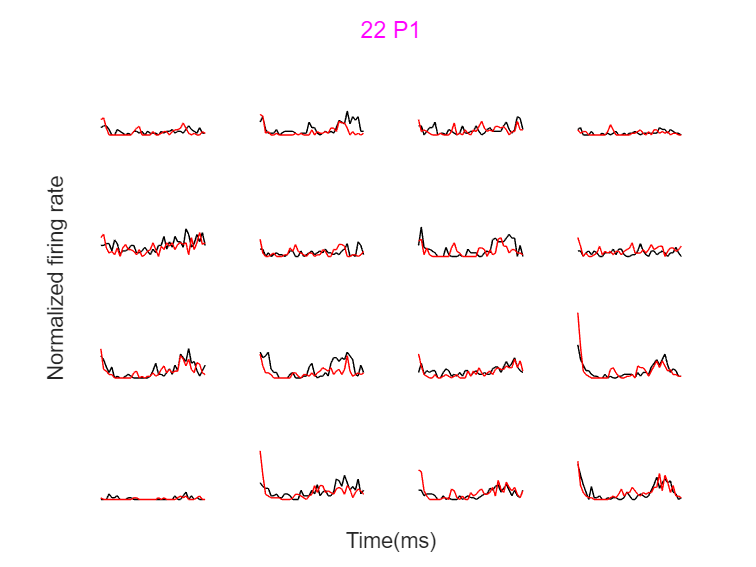

t=tiledlayout(4,4);
for i=1:16
    if i<11 
        formatSpec = 'Raw_P%d_Ch_00%d.mat';
        aaa=i-1;
        str = sprintf(formatSpec,P,aaa);
    else
        formatSpec = 'Raw_P%d_Ch_0%d.mat';
        aaa = i-1;
        str = sprintf(formatSpec,P,aaa);
    end
    for j=1:2
        x=load(fullfile(datadir{j},str));
        x=double(x.data(1:4400000)); % fino a 4400k per 1 stim, dopo 4400k per secondo stim
        xf = filtfilt(B,A,x);
        [~,ax]=findpeaks(xf, 'MinPeakHeight',500,'MinPeakDistance',25000);
        thx=7*std(xf((ax(end)+10000):end));
        [ampx,stx] = differential_th(xf, wdw_length, thx);
        psthx=psth(stx, wdw, bin, ax);
        count(j,:) = mean(psthx,1);
    end
    nexttile
    plot(time,count(1,2:end),'k') % ,2:end for all except p=2,s=2
    axis off
    hold on
    plot(time, count(2,2:end),'r')
    axis off
    ylim([0 1.5])
    a1= trapz(time,count(1,2:end));
a2= trapz(time,count(2,2:end));
dif(i)=(a1-a2)*100/a1;
end
title(t,'22 P1','Color','magenta')
ax = gca;
ax.TitleHorizontalAlignment = 'left';
xlabel(t,'Time(ms)')
ylabel(t,'Normalized firing rate')
%legend('Pre-lesion','Post-lesion','Location', 'bestoutside');
ylim([0 1.5])